clear all, close all

F = tf([1 11 10], [1 4 8 0 0])


F =
 
    s^2 + 11 s + 10
  -------------------
  s^4 + 4 s^3 + 8 s^2
 
Continuous-time transfer function.



s = tf('s');

Punto a)

F ha due poli nell'origine -> va moltiplicato per s^2

K_f = dcgain(s^2 * F)

K_f = 1.2500

Singolarità

zeri = zero(F)

zeri =    -10
    -1


poli = pole(F)

poli =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 2.0000i


damp(F)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -2.00e+00 + 2.00e+00i     7.07e-01       2.83e+00         5.00e-01    
 -2.00e+00 - 2.00e+00i     7.07e-01       2.83e+00         5.00e-01    


Punto b)

K_r = 1;
K_c = 1;

Ga = K_c/K_r * F


Ga =
 
    s^2 + 11 s + 10
  -------------------
  s^4 + 4 s^3 + 8 s^2
 
Continuous-time transfer function.



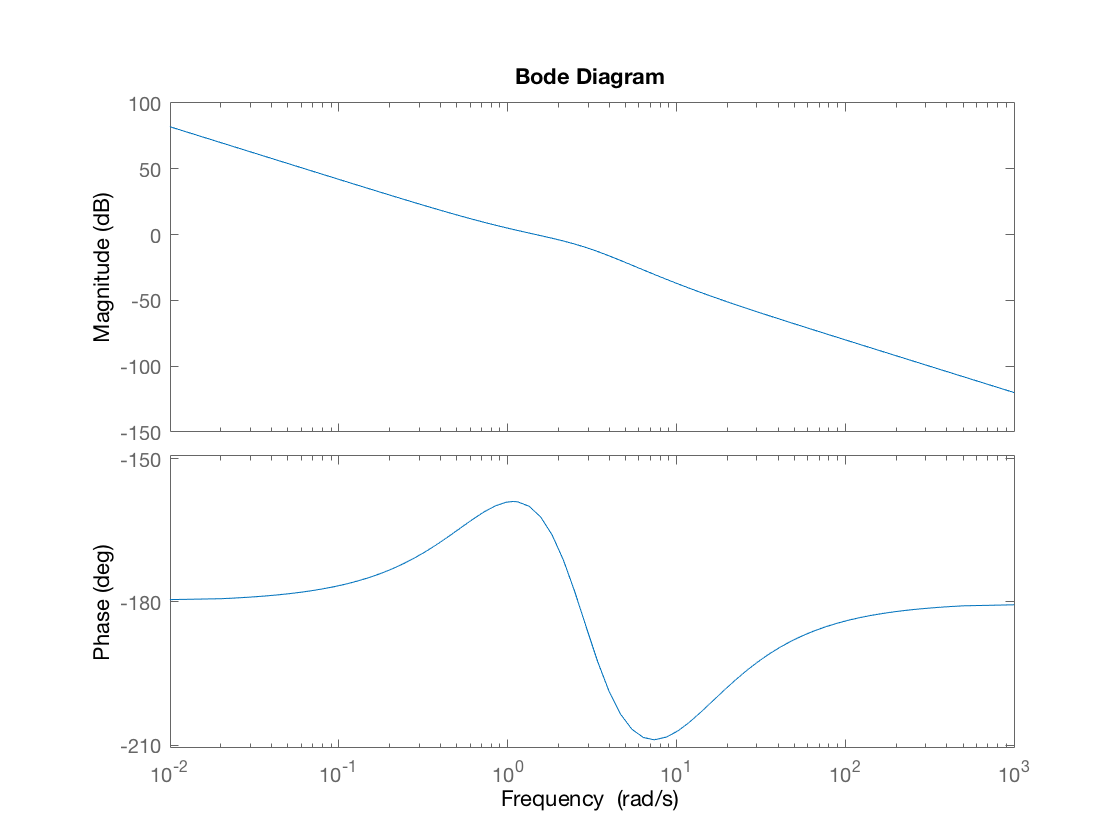

figure(1)
bode(Ga)

Punto c)

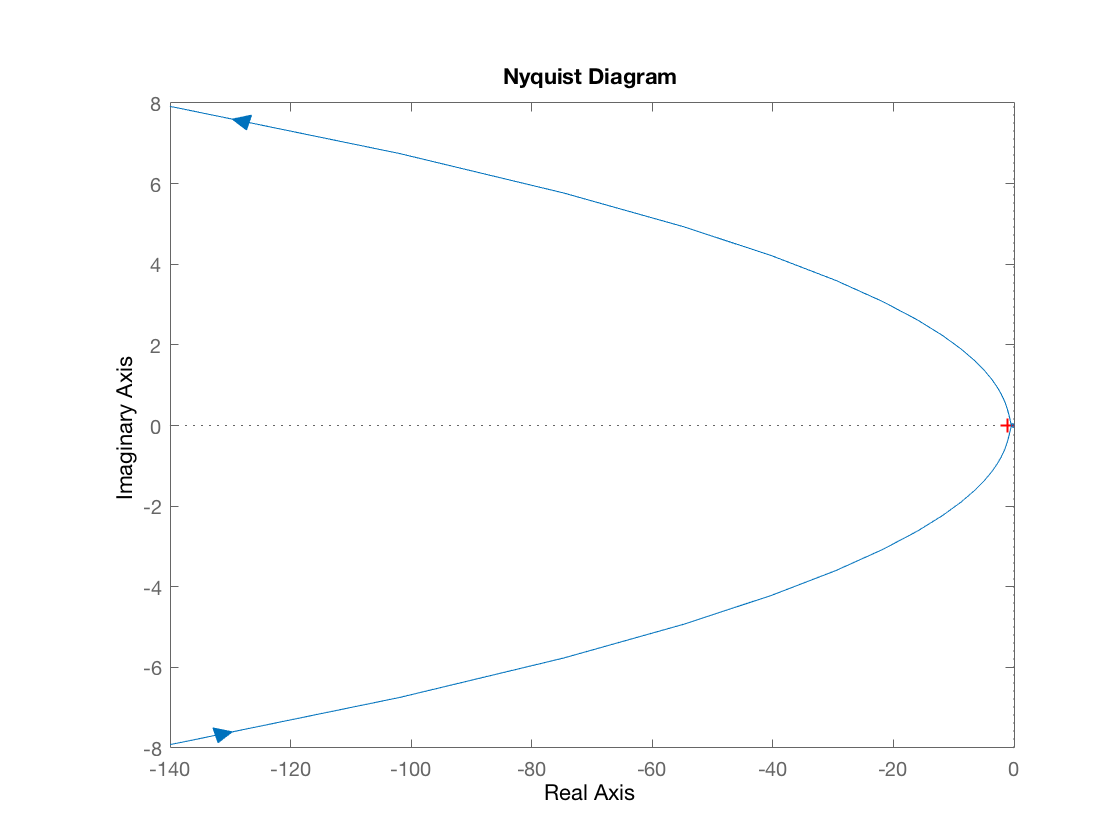

figure(2)
nyquist(Ga)